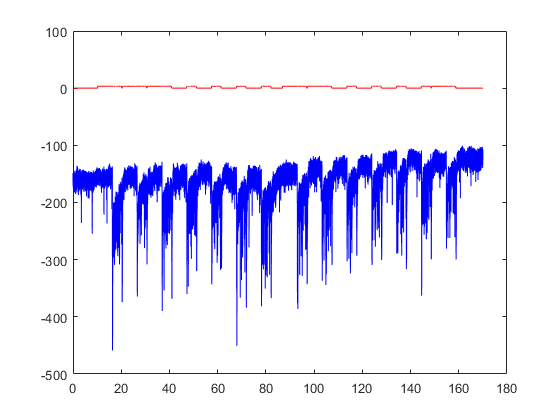

% This is an example how to analyze voltage clamp data
% 1, import data, use data from 430s to 600s
vc = readLabChart('VC.mat','interval',[430,600]);

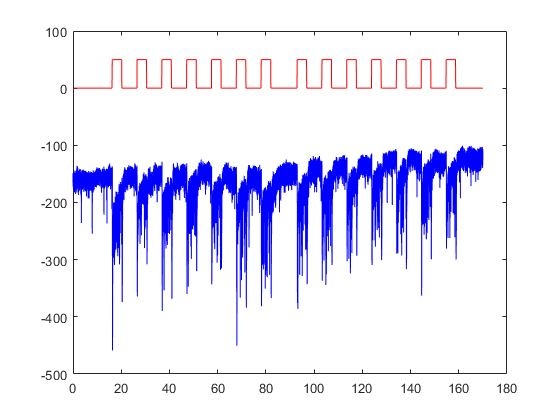

% 2.correct stimulus, due to software problem. After inspection, we found
% that stimulus 1,2,3,8,9,14 have errors, and we want set the amplitude of
% the stimulus to a different value, e.g., 50 in this case for better
% visulization
vc.correctSti([1,2,3,8,9,14],50);
figure,vc.plt;

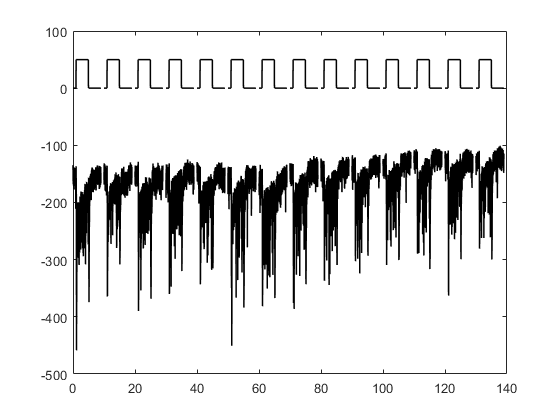

% 3. segment all traces, so that we can look into individual traces, or
% average traces, measure traces more conveniently. In this case, stimulus
% is 4s, we define 1s for pre-stimulus, and the whole length is 6s
vc.segtrace(1,9);

% 4, now we can look into individual traces or show all segmented traces,
% e.g., all traces
figure,vc.plt('method','fixedlength');

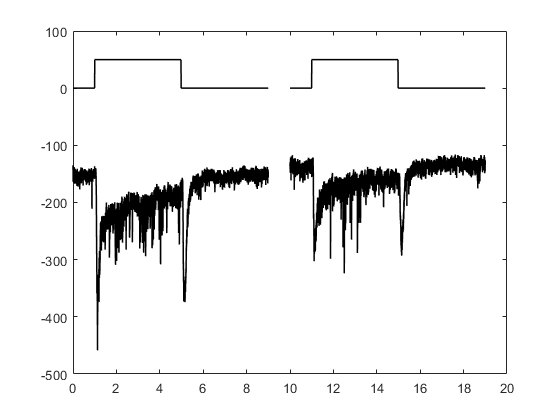

% individual traces
figure,vc.plt('method','fixedlength','sti',[1,10]);

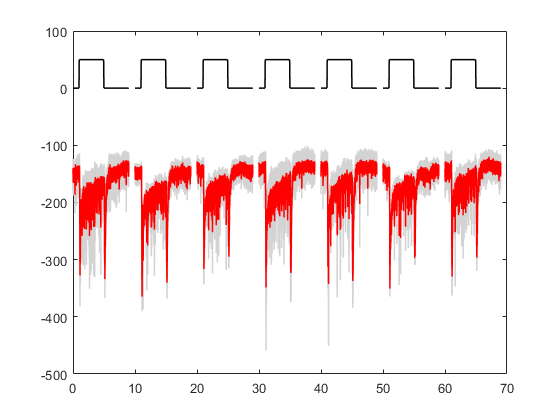

% In this case, there are 7 different stimulus, each given twice, as 
% 7,11;3,8;5,10;1,14;6,12;2,9;4,13
% To average the responses for each stimulus, we can first define the
% stimulus pattern:
pat{1} = [7,11]; pat{2} = [3,8]; pat{3} = [5,10]; pat{4} = [1,14];
pat{5} = [6,12]; pat{6} = [2,9]; pat{7} = [4,13];
vc.setStiPattern(pat);

% then we can get the averaged responses by
figure,vc.plt('method','average');

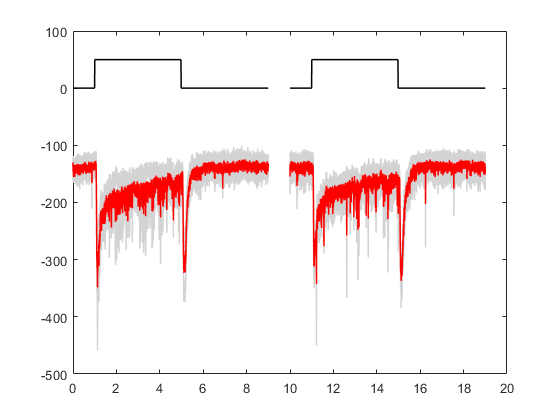

% or we can only plot the averaged response for specific stimulus, e.g.,
% stimulus pattern 4,5
figure,vc.plt('method','average','pat',[4,5]);

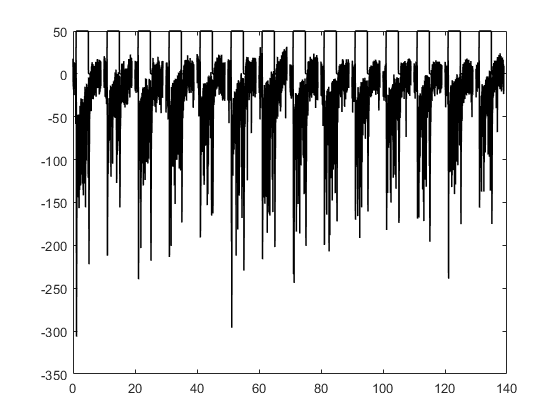

% Note, during experiments,usually the baseline would change during time.
% The examples are above are without baseline correction. It is better to
% correct the baseline before average. Here for every segmented trace, we
% correct their baseline using a mode value from the pre-stimulus interval
for i = 1:size(vc.seg.d,2)
    prestimlength = 1 * vc.sr;
    vc.seg.d(:,i) = adjustbaseline(vc.seg.d(:,i),'prestimlength',prestimlength);
end

% now let's look at traces after baseline corrections
figure,vc.plt('method','fixedlength');

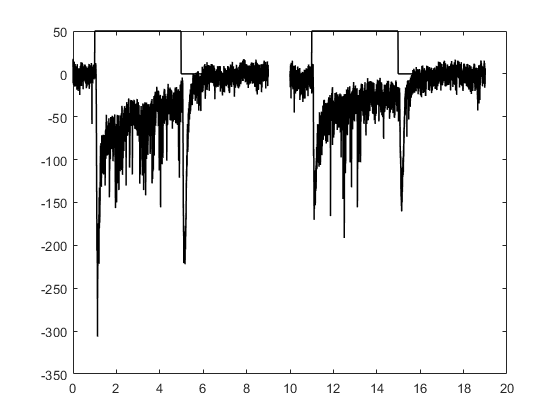

% individual traces
figure,vc.plt('method','fixedlength','sti',[1,10]);

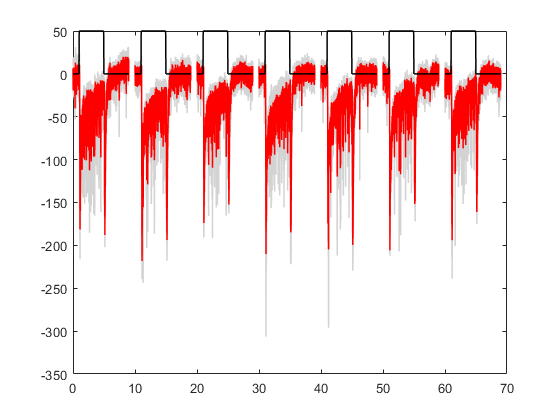

% averaged traces
figure,vc.plt('method','average');

% 5. last we want to measure the response amplitude or area
% e.g., to get tha peak amplitude for all responses, we define an onlength
% and an offlength to find the peak, in this case, both are set to 1s
vc.getPeakAmplitude(1,1);

% 1st row is on, 2nd row is off
vc.resp.peakAmp

ans =  -306.3750 -212.1250 -239.5000 -213.5000 -190.8750 -296.1250 -216.1250 -243.7500 -199.5000 -170.1250 -182.1250 -168.8750 -238.8750 -156.0000
 -222.0000 -155.7500 -218.0000 -173.3750 -162.7500 -229.5000 -202.0000 -200.6250 -172.0000 -160.5000 -173.7500 -195.7500 -175.2500 -175.0000


% or response area, by define the interval for both on and off as 4s
vc.getArea(4);
vc.resp.area

ans = 	1.0e+05 *

    9.5288    9.5288    9.5288    9.5288    9.5288    9.5288    9.5288    9.5288    9.5288    9.5288    9.5288    9.5288    9.5288    9.5288
    2.1035    2.1035    2.1035    2.1034    2.1035    2.1035    2.1034    2.1035    2.1035    2.1034    2.1034    2.1035    2.1034    2.1035
